# Taller 1, puntos 11 y 12: Adaline sobre las particiones de banknote

clear; close all; clc
load banknote_splits.mat

## Parametros

umbral = 0.5; salida = [0 1]; error_min = 1e-3; max_epocas = 500; semilla = 1;
alphas = [0.0001 0.001 0.005 0.01 0.05];

## Entrenamiento con y sin escalar

Sin escalar, la curtosis llega a 17 y con alpha grande el error se dispara

R = table();
for escalar = [false true]
    for k = 1:4
        Xtr = S(k).Xtr; Xte = S(k).Xte; dtr = S(k).ytr; dte = S(k).yte;
        if escalar
            mn = min(Xtr); mx = max(Xtr);
            Xtr = (Xtr - mn) ./ (mx - mn);  Xte = (Xte - mn) ./ (mx - mn);
        end
        for a = alphas
            [w, b, ep, EC] = adaline(Xtr, dtr, a, error_min, max_epocas, semilla);
            acc_tr = 100*mean(predecir(Xtr, w, b, umbral, salida) == dtr);
            acc_te = 100*mean(predecir(Xte, w, b, umbral, salida) == dte);
            R = [R; table(escalar, k, {sprintf('%d-%d', 100*S(k).p, 100-100*S(k).p)}, a, ep, EC(end), acc_tr, acc_te, ...
                 'VariableNames', {'Escalado','k','Particion','Alpha','Epocas','EC_final','Exact_train','Exact_test'})];
        end
    end
end
R

R = 40×8 table
    Escalado    k    Particion    Alpha     Epocas    EC_final    Exact_train    Exact_test
    ________    _    _________    ______    ______    ________    ___________    __________

     false      1    {'60-40'}    0.0001     225       13.177       97.934         96.721  
     false      1    {'60-40'}     0.001      41       13.938       98.056          97.45  
     false      1    {'60-40'}     0.005      11       18.925        97.57         96.539  
     false      1    {'60-40'}      0.01       6       39.003       95.383         93.989  
     false      1    {'60-40'}      0.05       2          Inf       37.181         36.066  
     false      2    {'70-30'}    0.0001     199       15.203       98.021         96.117  
     false      2    {'70-30'}     0.001      36       16.079       98.542         96.359  
     false      2    {'70-30'}     0.005      10       21.961        98.75         97.087  
     false      2    {'70-30'}      0.01       6       46.772   

## Grafica

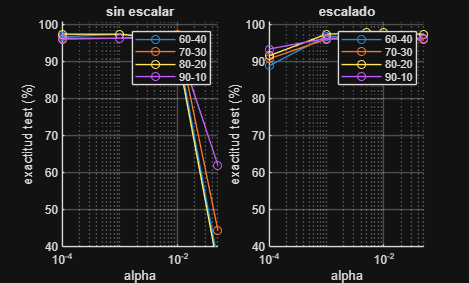

figure
titulos = {'sin escalar', 'escalado'};
for e = 1:2
    subplot(1,2,e); hold on
    for k = 1:4
        m = R.Escalado == (e==2) & R.k == k;
        plot(R.Alpha(m), R.Exact_test(m), '-o', 'DisplayName', R.Particion{find(m,1)});
    end
    set(gca, 'XScale', 'log'); grid on; ylim([40 101]); legend
    xlabel('alpha'); ylabel('exactitud test (%)'); title(titulos{e});
end

## Mejor caso: curva de error y matriz de confusion

[~, i] = max(R.Exact_test);
R(i, :)

ans = 1×8 table
    Escalado    k    Particion    Alpha    Epocas    EC_final    Exact_train    Exact_test
    ________    _    _________    _____    ______    ________    ___________    __________

     true       3    {'80-20'}    0.005     287       18.724       98.087         97.81   


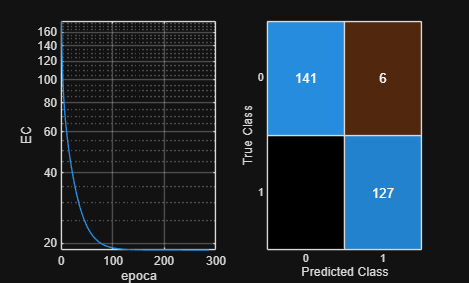

k = R.k(i);
Xtr = S(k).Xtr; Xte = S(k).Xte;
if R.Escalado(i)
    mn = min(Xtr); mx = max(Xtr);
    Xtr = (Xtr - mn) ./ (mx - mn);  Xte = (Xte - mn) ./ (mx - mn);
end
[w, b, ~, EC] = adaline(Xtr, S(k).ytr, R.Alpha(i), error_min, max_epocas, semilla);
figure
subplot(1,2,1); semilogy(EC); grid on; xlabel('epoca'); ylabel('EC')
subplot(1,2,2); confusionchart(S(k).yte, predecir(Xte, w, b, umbral, salida))

## Perceptron contra Adaline, particion 80-20 escalada

Xtr = S(3).Xtr; Xte = S(3).Xte;
mn = min(Xtr); mx = max(Xtr);
Xtr = (Xtr - mn) ./ (mx - mn);  Xte = (Xte - mn) ./ (mx - mn);
R2 = table();
for a = [0.001 0.01 0.05 0.1]
    [wp, bp, ep_p] = perceptron(Xtr, S(3).ytr, 3, a, 0.5, [0 1], 500, 1);
    [wa, ba, ep_a] = adaline(Xtr, S(3).ytr, a, error_min, max_epocas, 1);
    R2 = [R2; table(a, ep_p, 100*mean(predecir(Xte,wp,bp,0.5,[0 1]) == S(3).yte), ...
                    ep_a, 100*mean(predecir(Xte,wa,ba,0.5,[0 1]) == S(3).yte), ...
          'VariableNames', {'Alpha','Epocas_perc','Exact_perc','Epocas_ada','Exact_ada'})];
end
R2

R2 = 4×5 table
    Alpha    Epocas_perc    Exact_perc    Epocas_ada    Exact_ada
    _____    ___________    __________    __________    _________

    0.001        500          98.905         500         97.445  
     0.01        500          98.905         154          97.81  
     0.05        500          98.905          46         97.445  
      0.1        500          97.445          26         97.445  
